Task1:

Assumption:

Fire is only a candle

Parrot minidrone moves forward until a fire is detected. If a fire is detected the drone flies as long as the fire is not visible any more. Reason: to get a better image from the situation. 

During this flight persons and cars are detected. 

Drone turns and flies back until a green piece (f.e green a4 paper) is detected.

step 1

step 2

step 3

step 4

step 5

step 1

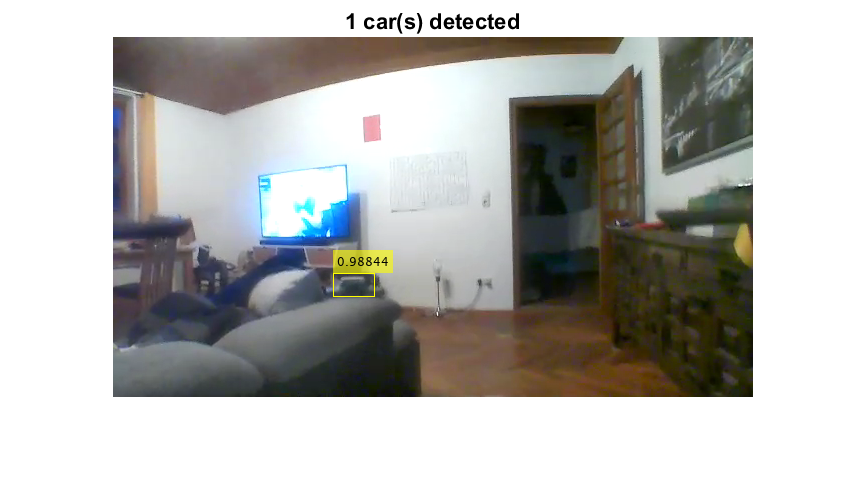

step 2step 3step 4step 5

no green...
no green...
no green...
no green...
Green!


pause('on')
parrotObj = parrot();
try
    takeoff(parrotObj);
    %moveup(parrotObj,0.1,1); % move up for 0.1 sec 1 m/s
    
    [height,time] = readHeight(parrotObj)
    camObj = camera(parrotObj,'FPV');
    %livestream = preview(camObj)
    
    [odSnaps,facesCounter, carsCounter, snap, fireBoundBox, fireFound] = flyForwardUntilFireFound(true, parrotObj, camObj);
    pause(1);
    if (fireFound)
        [odSnaps,facesCounter, carsCounter, ~, ~, fireNotFound] =   flyForwardUntilFireFound(false, parrotObj, camObj);
    end
    
    pause(1);
    turn(parrotObj,deg2rad(-180));
    pause(1);
    
    while ~findGreenEndpoint(snapshot(camObj))
        %moveforward(parrotObj,flightDuration);
        move(parrotObj, 0.2,'pitch' ,deg2rad(-1));
        pause(2);
    end
    
catch e
    exception1 = e
end

pause('off')
try
    land(parrotObj);
catch e
end
clear parrotObj;
clear camObj;

